# Create "Automobile Data.csv" for Quizzes 2 and 3

**Run this script.** It will create a file named "Automobile Data.csv" in your current folder. You will use this data multiple times.

### Optional Details

This description is here for those who want to learn more about how the CSV file for quiz 3 is created.

Many sample data sets are included with MATLAB and used as examples in the documentation. One such data set is `carbig`. The first line of code using the load command specifies variables contained in the file to import. The data is not organized into a table and is instead imported as many separate variables.

load carbig Mfg Model Model_Year MPG Weight Cylinders Horsepower Acceleration Displacement

The data is organized into a table using the `table` function. This is required for many real-world applications. For example, when studying air quality for a region, you may have different types of sensors (wind speed, temperature, pollution readings for different particulates) and need to import the data separately, then organize the data into a table for analysis.

After creating the table, it is saved to the Current Folder using the `writetable` function.

T = table(Mfg, Model, Model_Year, MPG, Weight, Cylinders, Horsepower, Acceleration, Displacement);
writetable(T, "Automobile Data.csv")
disp("Automobile Data.csv was added to the current folder")

Automobile Data.csv was added to the current folder


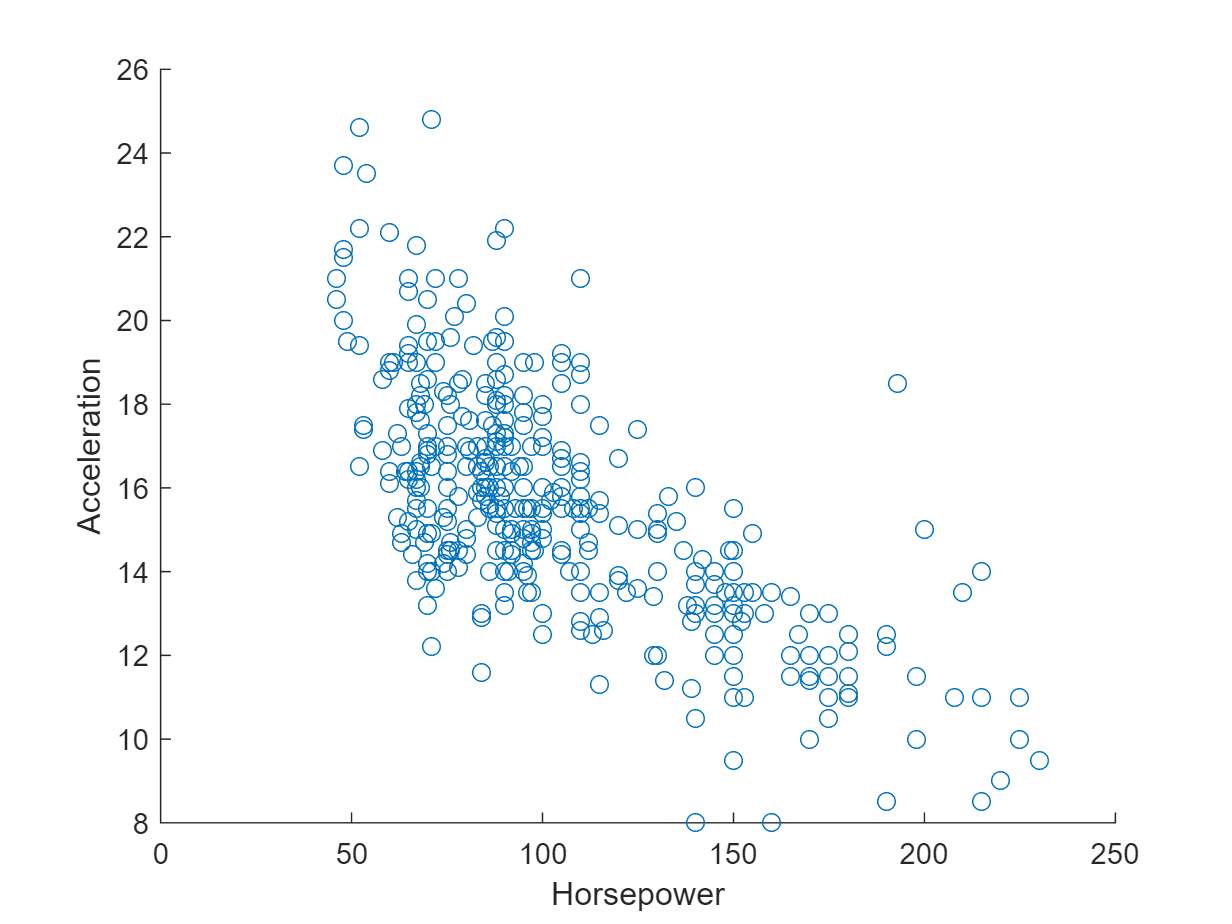

scatter(T,"Horsepower","Acceleration")

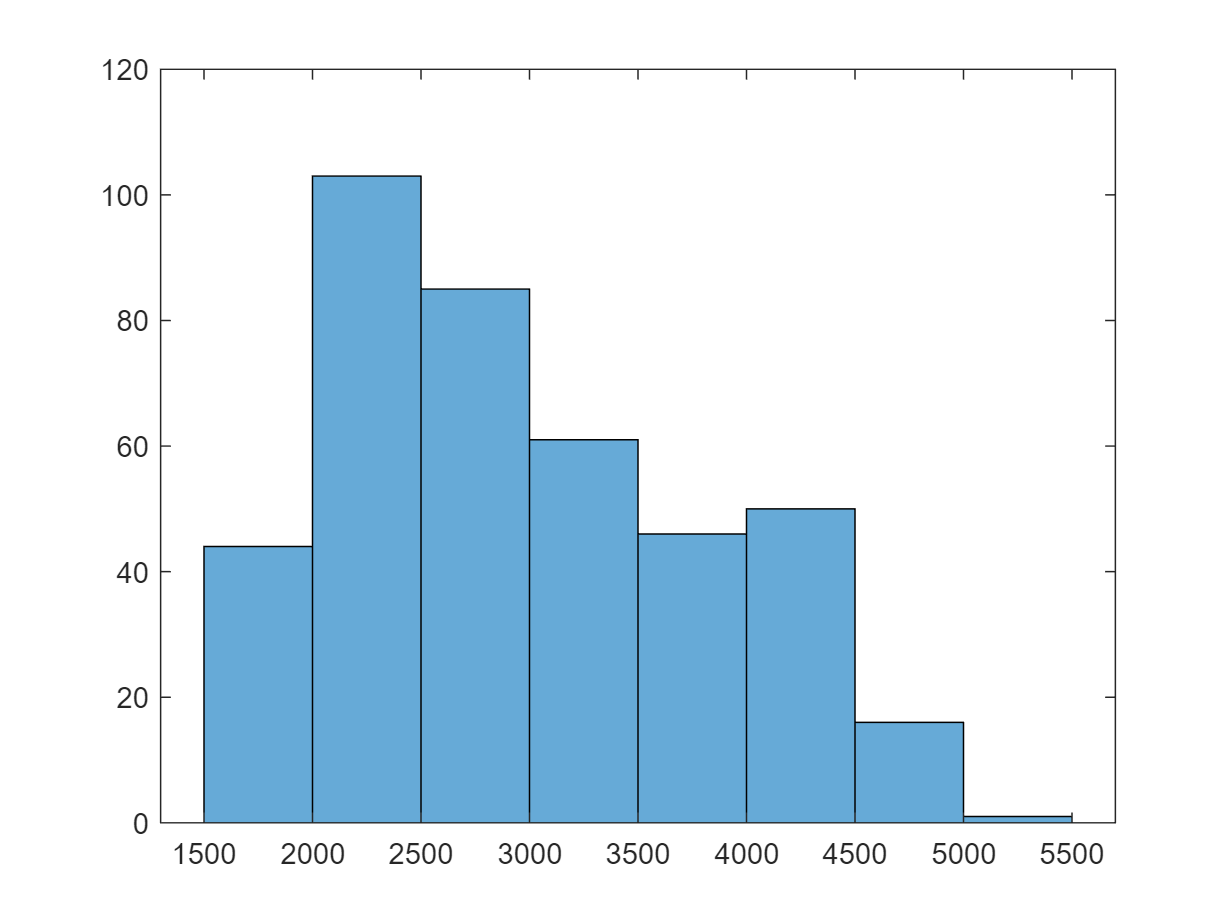

figure, histogram(T.Weight)

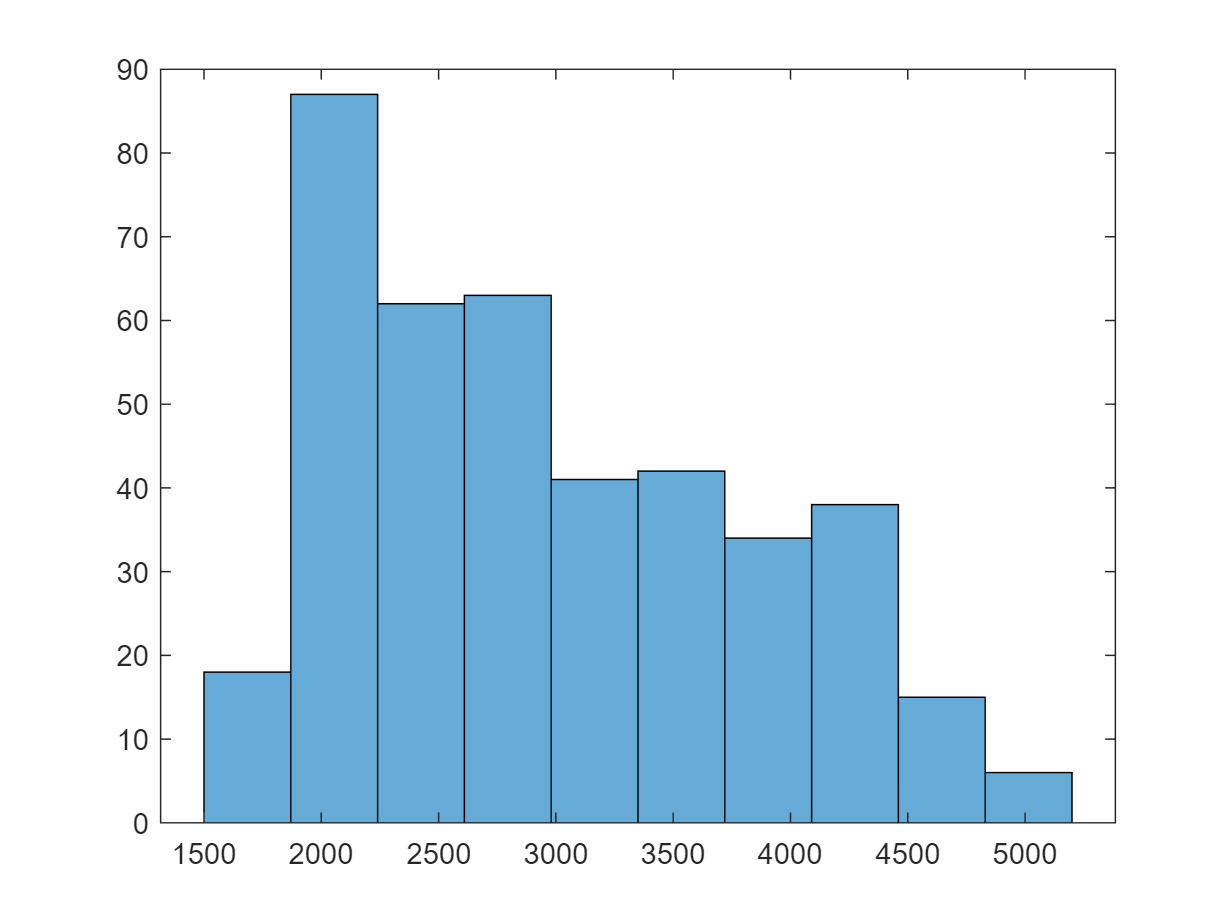

figure, histogram(T.Weight,10)

T

T = 406×9 table
       Mfg                      Model                    Model_Year    MPG    Weight    Cylinders    Horsepower    Acceleration    Displacement
    _________    ____________________________________    __________    ___    ______    _________    __________    ____________    ____________

    chevrolet    chevrolet chevelle malibu                   70         18     3504         8           130              12            307     
    buick        buick skylark 320                           70         15     3693         8           165            11.5            350     
    plymouth     plymouth satellite                          70         18     3436         8        

T.Mfg = categorical(cellstr(T.Mfg));
G = groupsummary(T,"Mfg");
G = sortrows(G,'GroupCount','descend')

G = 30×2 table
       Mfg        GroupCount
    __________    __________

    ford              54    
    chevrolet         48    
    plymouth          32    
    amc               29    
    dodge             28    
    toyota            26    
    datsun            23    
    volkswagen        23    
    buick             17    
    pontiac           16    
    honda             13    
    mazda             12    
    mercury           11    
    oldsmobile        10    
    fiat               8    
    peugeot            8    


sortrows(T,"MPG","descend","MissingPlacement","last")

ans = 406×9 table
       Mfg                       Model                    Model_Year    MPG     Weight    Cylinders    Horsepower    Acceleration    Displacement
    __________    ____________________________________    __________    ____    ______    _________    __________    ____________    ____________

    mazda         mazda glc                                   80        46.6     2110         4            65            17.9             86     
    honda         honda civic 1500 gl                         80        44.6     1850         4            67            13.8             91     
    volkswagen    volkswagen rabbit c (diesel)                80        44.3     2085      

T8cyl = T(T.Cylinders==8,:);
G8cyl = sortrows(T8cyl,"MPG","descend","MissingPlacement","last");
G8cyl.Model(1,:)

ans = 'oldsmobile cutlass ls               '

T70s = T(and(70<=T.Model_Year,T.Model_Year<=79),:)

T70s = 316×9 table
       Mfg                      Model                    Model_Year    MPG    Weight    Cylinders    Horsepower    Acceleration    Displacement
    _________    ____________________________________    __________    ___    ______    _________    __________    ____________    ____________

    chevrolet    chevrolet chevelle malibu                   70         18     3504         8           130              12            307     
    buick        buick skylark 320                           70         15     3693         8           165            11.5            350     
    plymouth     plymouth satellite                          70         18     3436         8     

T70s_rmmissing = rmmissing(T70s,'DataVariables','MPG')

T70s_rmmissing = 309×9 table
       Mfg                      Model                    Model_Year    MPG    Weight    Cylinders    Horsepower    Acceleration    Displacement
    _________    ____________________________________    __________    ___    ______    _________    __________    ____________    ____________

    chevrolet    chevrolet chevelle malibu                   70        18      3504         8           130              12            307     
    buick        buick skylark 320                           70        15      3693         8           165            11.5            350     
    plymouth     plymouth satellite                          70        18      3436     

T.KMPL = 0.425 * T.MPG;

Finally, the variables created are cleared from your workspace to prevent any naming conflicts while you work on the quiz.

clear T Mfg Model Model_Year MPG Weight Cylinders Horsepower Acceleration Displacement